addpath 'C:\Users\wsccs\Downloads\PRML\PattRecClasses\GetSpeechFeatures';
addpath 'C:\Users\wsccs\Downloads\PRML\PattRecClasses';
cd Actor_01;
fileName = ls;
feature = [];
featureLength = [];
[x0, fs] = audioread(fileName(3,:));
[mfccs1,spec1,f1,t0]=GetSpeechFeatures(x0(:,1),fs,0.03,13);
test = feature_normalized(mfccs1);

for i = 4:62
    [x, fs] = audioread(fileName(i,:));
    [mfccs1,spec1,f1,t1]=GetSpeechFeatures(x(:,1),fs,0.03,13);
    check = isfinite(mfccs1);
    if all(all(check))
        mfccs_n1 = feature_normalized(mfccs1);
        feature = [feature mfccs_n1];
        featureLength = [featureLength size(mfccs_n1,2)];
    end
end

cd ..;

nStates = 25;
pD = [];
iter = 50;
for i = 1:nStates
    pD = [pD GaussD('Mean',3*rand(39,1),'Covariance',eye(39)/10)];
end

hmm=MakeErgodicHMM(nStates,10,pD,feature,featureLength);

lP=logprob(hmm,feature(:,1:217));

% variance = zeros(nStates,iter);
% mu = zeros(nStates,iter);
for i = 1:iter
    [hmm,logprobs] =train(hmm,feature,featureLength,10,log(1.01));
    lP = [lP logprob(hmm,feature(:,1:217))];
%     for j = 1:nStates
%         [V,D] = eig(hmm.OutputDistr(j).Covariance);
%         [M,I] = max(D,[],'all','linear');
%         I = mod(I, 39);
%         variance(j,i) = 1/M;
%         mu(j,i) = V(I,:) * hmm.OutputDistr(j).Mean;
%     end
end

[S,logP]=viterbi(hmm,feature(:,1:217))

S =      1     1    11     1     4    25    25    22     6     6     6     6     6     6     6     6     6     6     6     1     6     6     6     6     6     5     1     6     6     6     6    18    18     6     6     6     6     6     6     6     1     6     6     6     6     6     1     1     6    18


logP = 4.1792e+04

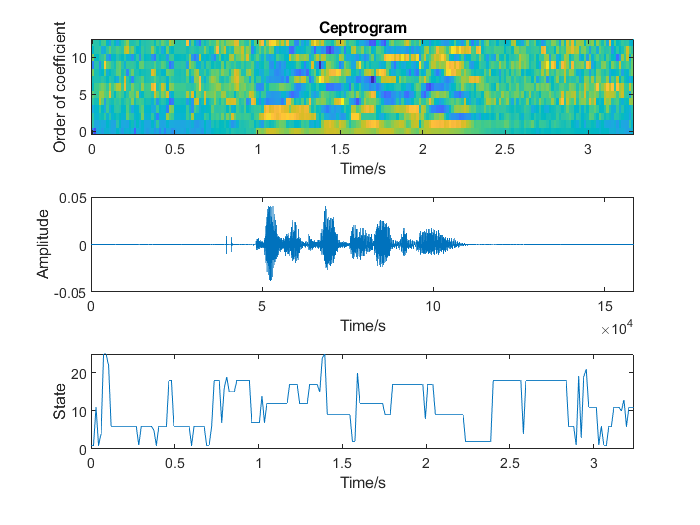

subplot(3,1,1);
imagesc(t0,0:12,test(1:13,:));
% h = colorbar;
% ylabel(h, 'Amplitude');
axis xy;
xlabel('Time/s');
ylabel('Order of coefficient');
title('Ceptrogram');

subplot(3,1,2);
plot(1:length(x0),x0);
xlim([0 length(x0)]);
xlabel('Time/s');
ylabel('Amplitude');
% title('Female');

subplot(3,1,3);
plot(t0(1:length(S),1),S);
xlim([0 t0(length(S))]);
xlabel('Time/s');
ylabel('State');

% title('Female');

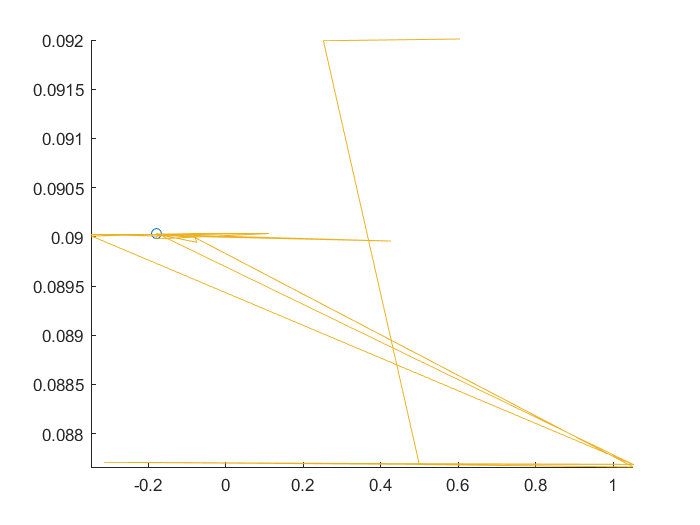

mu1 = real(mu);
figure();
i = 19;
t = 1:50;
x = mu1(i,t);
y = variance(i,t);
comet(x,y);

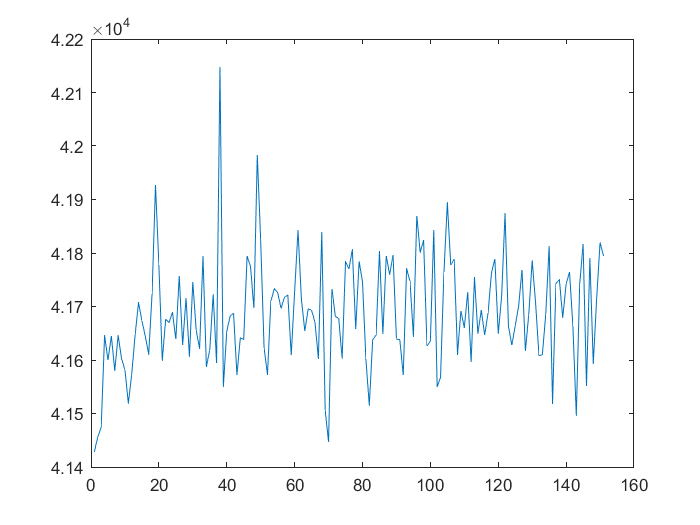

figure();
plot(1:length(lP),lP);